# Демодуляция. Часть 1.

# Double Sideband Transmitted Carrier 

# (AM-DSB-TC)

### 1. Когерентная демодуляция

Для начала рассмотрим когерентный способ демодуляции АМ-сигнала. Для этого принятый сигнал нужно смешать (перемножить) с колебанием, которое является копией несущей. Затем результат необходимо пропустить через фильтр нижних частот (ФНЧ). Схема когерентного демодулятора представлена ниже:

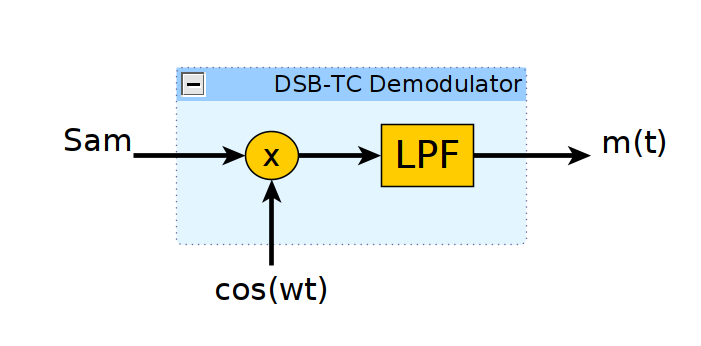

В аналитическом виде описанные выше преобразования можно представить следующим образом. Пусть принятый АМ-сигнал имеет вид:

$s_{\textrm{am}} \left(t\right)=\left(m\left(t\right)+A_c \right)\cdot \cos \left(2\pi f_c t\right)$,

где $m\left(t\right)$ - информационное сообщение, $A_c$ - амплитуда несущей, $f_c$ - частота несущей.

После перемножения с гармоничеким сигналом, частота и фаза которого совпадают с несущей, получим:

$s_{\textrm{mix}} \left(t\right)=\left(m\left(t\right)+A_c \right)\cdot \cos \left(2\pi f_c t\right)\cdot \cos \left(2\pi f_c t\right)$.

Вспомнив правило произведения косинусов, можем записать результат умножения в виде:

$s_{\textrm{mix}} \left(t\right)=\frac{1}{2}\left(m\left(t\right)+A_c \right)+\frac{1}{2}\left(m\left(t\right)+A_c \right)\cdot \cos \left(2\pi \cdot 2f_c \cdot t\right)$.

Таким образом, сигнал на выходе смесителя явялется суммой инфомационного сообщения (с добавленной постоянной составляющей $A_c$) и сигнала на удвоенной частоте несущей $2f_c$. После пропускания данной суммы через ФНЧ, второе слагаемое исчезнет, и мы получим:

$s_{\textrm{LPF}} \left(t\right)=\frac{1}{2}\left(m\left(t\right)+A_c \right)$.

То есть восстановленный сигнал является масштабированной копией исходного сообщения с добавленной постоянной составляющей. 

Сложность при таком методе демодуляции заключается в том, что колебание в смесителе должно точно совпадать по частоте и фазе с несущей. Очевидно, что на практике генераторы на передающей и приемной сторонах не могут быть абсолютно идентичными. Между ними всегда есть некоторая расстройка. Рассмотрим вляние такого рассогласования на качество  демодуляции. Пусть рассогласование по частоте и фазе между колебанием в смесителе и несущей равны $\Delta f$ и $\Delta \phi$ соотвветственно. В этом случае на выходе смесителя получим:


$$\begin{array}{l}
s_{\textrm{mix}} \left(t\right)=\left(m\left(t\right)+A_c \right)\cdot \cos \left(2\pi f_c t\right)\cdot \cos \left(2\pi \left(f_c +\Delta f\right)t+\Delta \phi \right)=\\
=\frac{1}{2}\left(m\left(t\right)+A_c \right)\cdot \cos \left(2\pi \Delta \textrm{ft}+\Delta \phi \right)+\textrm{слагаемое}\;с\;\textrm{удвоенной}\;\textrm{частотой}\ldotp 
\end{array}$$


После ФНЧ слагаемое на удвоенной частоте исчезнет:

$s_{\textrm{LPF}} \left(t\right)=\frac{1}{2}\left(m\left(t\right)+A_c \right)\cdot \cos \left(2\pi \Delta \textrm{ft}+\Delta \phi \right)$.

Для начала рассмотрим случай, когда присутствует только расстройка по фазе ($\Delta \mathrm{ft}=0$). Восстановленный сигнал примет вид:

$s_{\textrm{LPF}} \left(t\right)=\frac{1}{2}\left(m\left(t\right)+A_c \right)$$\cdot \cos \left(\Delta \phi \right)$.

Результат совпадает со случаем идеальной демодуляции за исключение того, что теперь присутствует дополнительное масштабирование на $\cos \left(\Delta \phi \right)$. Так как модуль косинуса меньше единицы, мы получаем дополнительное ослабление сигнала. В крайнем случае, когда $\Delta \phi =90$ градусов, сигнал на выходе ФНЧ будет равен нулю.

Теперь рассмотрим, к чему приведет ненулевая расстройка по частоте. На выходе ФНЧ получим:  

$s_{\textrm{LPF}} \left(t\right)=\frac{1}{2}\left(m\left(t\right)+A_c \right)\cdot \cos \left(2\pi \Delta \textrm{ft}\right)$.

Таким образом, восстановленное сообщение масштабируется на множитель $\cos \left(2\pi \Delta \textrm{ft}\right)$, амплитуда которого будет изменяться с частотой $\Delta f$. Ниже представлен скрипт, который демонстрирует когерентный метод демодуляции для аудиосообщения на несущей частоте 60кГц. С помощью переменных FreqOffset и PhaseOffset можно задать расстройку по частоте и фазе и на слух оценить оскажения сигнала. 

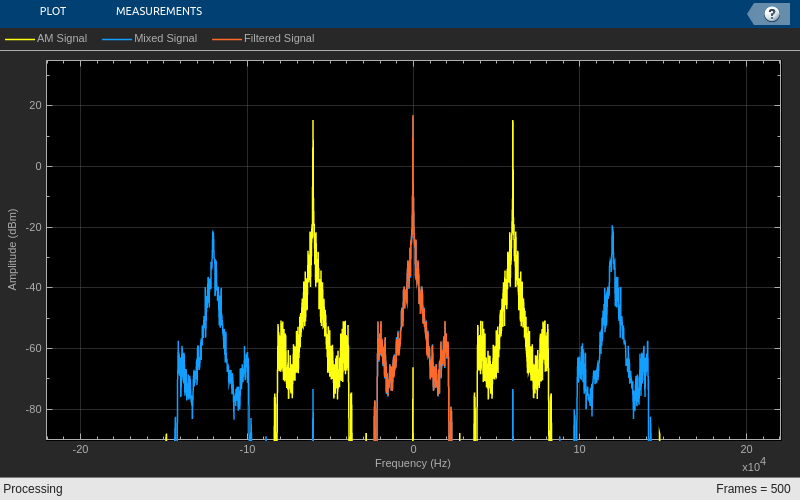

clc; clear; close all;

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 3;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации
Fc = 60e3;                % частота несущей

FreqOffset = 0;             % расстройка по частоте (Hz)
PhaseOffset = 0 * pi/180;   % расстройка по фазе (градусы)

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_TC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% генератор несущей
Carrier = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', Fc + FreqOffset,...
    'PhaseOffset', pi/2 + PhaseOffset...
    );

% рассчет коэффициентов фильтра нижних частот
cd matlab/DSB_TC;
H = Audio_Lowpass_FIR_Coeff();
cd ../..;

% создание объекта для фильтрации
LowpassFIR = dsp.FIRFilter(H.Numerator);

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Mixed Signal', 'Filtered Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и выделение синфазного канала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1);

    % смешивание АМ-сигнала и несущей
    MixedSignal = AmSignal .* Carrier();

    % фильтрация сигнала
    BasebandSignal = LowpassFIR(MixedSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp * DownSampler(BasebandSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([AmSignal MixedSignal BasebandSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены преобразования в частотной области. Желтым обозначен спектр принимаемого АМ-сигнала. Синим - спектр на выходе смесителя. Можно увидеть, что он состоит из информационного сообщения и сигнала на удвоенной частоте несущей. После фильтрации остается только информационное сообщение (красный).

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно оценить искажения аудиосигнала из-за рассогласования по фазе и частоте. При расстройке по фазе сигнал слышится слабее, но он не искажен. Расстройка по частоте приводит к ухудшению качества и появлению свистящих звуков.

В файле *DSB_TC_Receiver_Part_1_1.slx* представлена Simulink модель когерентного демодулятора, который ранее был реализован ввиде скрипта. 

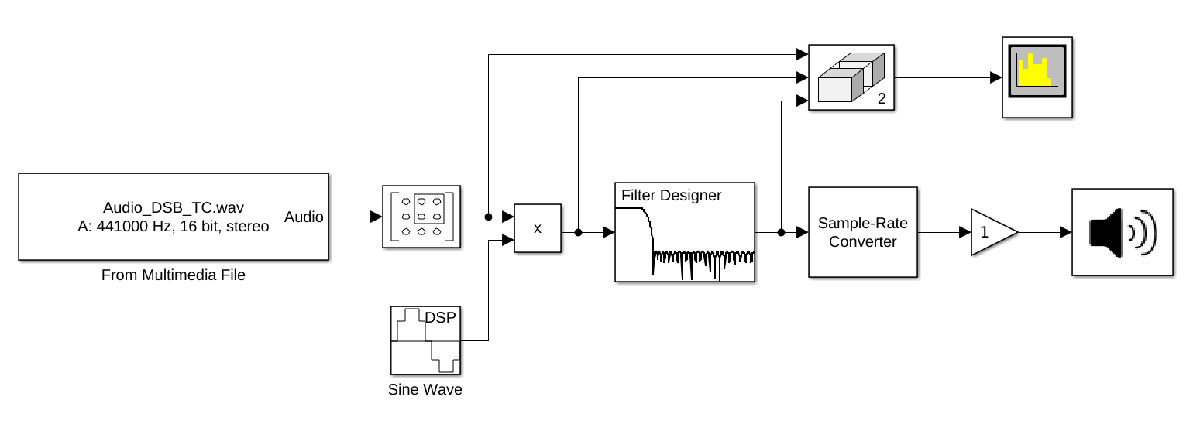

### 2. Когерентная демодуляция при квадратурном приеме

В случае, когда прием АМ-сигнала осуществляется квадратурным способом (например почти во всех SDR  приемниках), структуру когерентного демодулятора можно упростить:

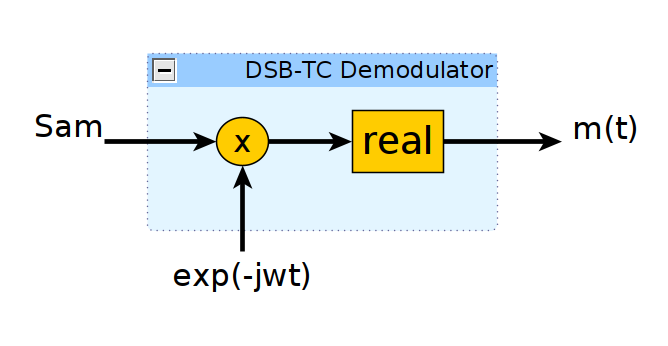

То есть, принятый АМ-сигнал, который является комплексным, нужно умножить на мнимую экспоненту, а потом просто выделить действительную часть.

В аналитическом виде описанные выше преобразования можно представить следующим образом. Пусть принятый АМ-сигнал имеет вид:

$s_{\textrm{am}} \left(t\right)=\left(m\left(t\right)+A_c \right)\cdot e^{2\pi f_c t}$,

где, как и ранее, $m\left(t\right)$ - информационное сообщение, $A_c$ - амплитуда несущей, $f_c$ - частота несущей.

После умножения на мнимую экспоненту, частота и фаза которой совпадает с несущей получим:

$s_{\textrm{mix}} \left(t\right)=\left(m\left(t\right)+A_c \right)\cdot e^{2\pi f_c t} \cdot e^{-2\pi f_c t} =m\left(t\right)+A_c$.

В идеале сигнал после умножения получится действительным и будет состоять из информационного сообщения и постоянной составяющей $A_c$. Поэтому выделение действительной части не внесет в сигнал никаких изменений: 

$\textrm{Re}\left\lbrace s_{\textrm{mix}} \left(t\right)\right\rbrace =m\left(t\right)+A_c$.

Теперь рассмотрим, что произойдет при наличие раастройки по фазе и частоте. Сигнал на выходе смесителя можно представить в виде:

$s_{\textrm{mix}} \left(t\right)=\left(m\left(t\right)+A_c \right)\cdot e^{2\pi f_c t} \cdot e^{-2\pi \left(f_c +\Delta f\right)t-\Delta \phi } =\left(m\left(t\right)+A_c \right)\cdot e^{-2\pi \Delta \textrm{ft}-\Delta \phi }$.

После вычисления действительной части получим:

$\textrm{Re}\left\lbrace s_{\textrm{mix}} \left(t\right)\right\rbrace =\left(m\left(t\right)+A_c \right)\cdot \cos \left(2\pi \Delta \textrm{ft}+\Delta \phi \right)$.

Данный результат совпадает с формулой, полученной в предыдущем разделе. Соответственно наличие расстройки по частоте и фазе будет приводить к аналогиным искажениям.

Ниже представлен скрипт для реализации когерентной демодуляции в случае квадратурного приема. С помощью переменных FreqOffset и PhaseOffset можно задать расстройку по частоте и фазе и на слух оценить оскажения сигнала.

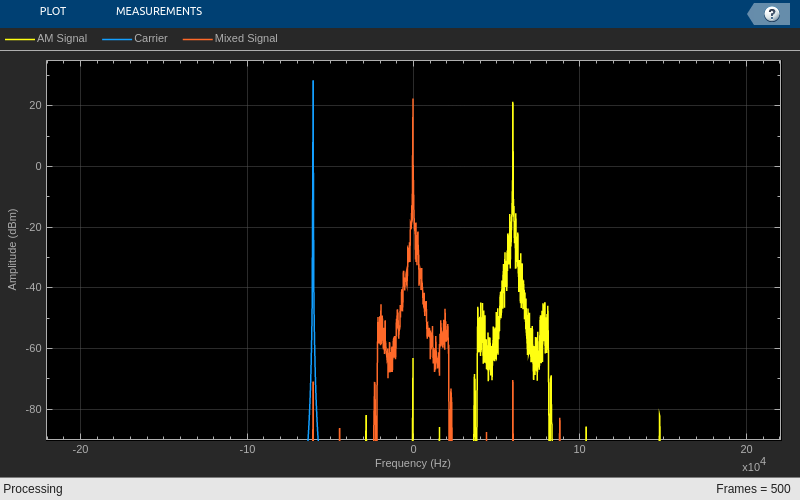

clc; clear; close all;

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 1;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации
Fc = 60e3;                % частота несущей

FreqOffset = 0;             % расстройка по частоте (Hz)
PhaseOffset = 0 * pi/180;   % расстройка по фазе (градусы)

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_TC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% генератор несущей
Carrier = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', [Fc + FreqOffset, Fc + FreqOffset],...
    'PhaseOffset', [pi/2 + PhaseOffset, PhaseOffset]...
    );

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Carrier', 'Mixed Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и формирование комплексного сигнала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1) + 1j*AmSignal(:,2);

    % получение несущей
    CarrierWave = Carrier();
    CarrierWave = CarrierWave(:,1) - 1j*CarrierWave(:,2);

    % смешивание АМ-сигнала и несущей
    MixedSignal = AmSignal .* CarrierWave;
    MixedSignal = real(MixedSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp*DownSampler(MixedSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([AmSignal CarrierWave MixedSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены преобразования в частотной области. Желтым обозначен спектр принимаемого АМ-сигнала. Так как прием квадратурный, спектр сигнала комплексный и расположен только в положительной области частот. Синим цветом представлена мнимая экспонента, а красным - сигнал на выходе смесителя. 

% проигрывание полученного сообщения
sound(Message, AudioFs);

В файле *DSB_TC_Receiver_Part_1_2.slx* представлена Simulink модель когерентного демодулятора в квадратурном случае. 

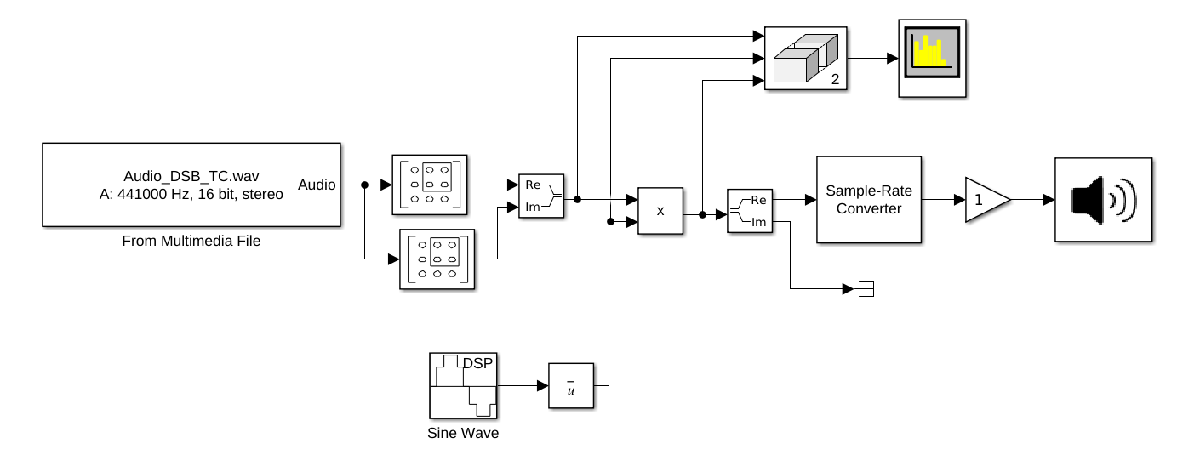

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR